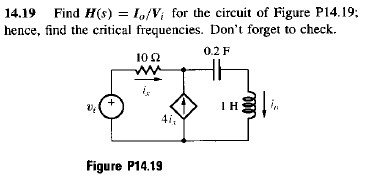

clc, clear, close all
format short g
syms s vi ix i0

c = 0.2;
l = 1;

z1 = 10;
z2 = 1/(s*c);
z3 = s*l;

Realizamos un analisis de mallas, debido a que tenemos una fuente dependiente, se usa una super malla con su ecuacion de restricción

sm = simplify(-vi + z1*ix + z2*i0 + z3*i0 == 0)

$$sm = i_{0}\,s^{2}+10\,\mathrm{ix}\,s+5\,i_{0}=s\,\mathrm{vi}\wedge s\neq 0$$

ec_restric = simplify(i0 - ix == 4*ix)

$$ec\_restric = i_{0}=5\,\mathrm{ix}$$

reemplazamos ix en la ecuacion de super malla

ix = i0/5;
sm = simplify(-vi + z1*ix + z2*i0 + z3*i0 == 0)

$$sm = s\,\mathrm{vi}=i_{0}\,\left(s^{2}+2\,s+5\right)\wedge s\neq 0$$

despejamos el factor *i0 / vi = H(s)*

h = s/(s^2+2*s+5)

$$h = \frac{s}{s^{2}+2\,s+5}$$

definimos la funcion de transferencia y encontramos los polos y zeros 

h = tf([1 0],[1 2 5]) %funcion de trasferencia

h =
 
        s
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



z = zero(h)

z =      0


p = pole(h)

p =            -1 +          2i
           -1 -          2i
